# การวิเคราะห์เชิงความถี่

# ตอนที่ 5 : อัตราส่วนขนาดและเฟสการเลื่อน (Magnitude Ratio & Phase Shift)

หากเรานำแนวคิดของการวิเคราะห์สัญญาณในรูปแบบของคลื่นไซน์มารวมกับระบบพลวัต เราจะสามารถศึกษาพฤติกรรมของผลตอบสนองได้ในเชิงความถี่ **การป้อนอินพุตที่เป็นคลื่นไซน์ให้กับระบบพลวัตทำให้ผลตอบสนองแบบคงตัวมีลักษณะเป็นคลื่นไซน์** ส่วนผลตอบสนองแบบชั่วครู่การจะลู่เข้าสู่ศูนย์ คงที่ หรือ โตเป็นอนันต์ก็เป็นได้ ดังนั้นเราจะสามารถเขียนเป็นสมการความสัมพันธ์ได้ดังต่อไปนี้


$$\begin{array}{l}
u\left(t\right)=R_{\textrm{in}} \cos \left(\omega t+\phi_{\textrm{in}} \right)\\
y\left(t\right)=y_t \left(t\right)+R_{\textrm{out}} \cos \left(\omega t+\phi_{\textrm{out}} \right)\\
G\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}
\end{array}$$


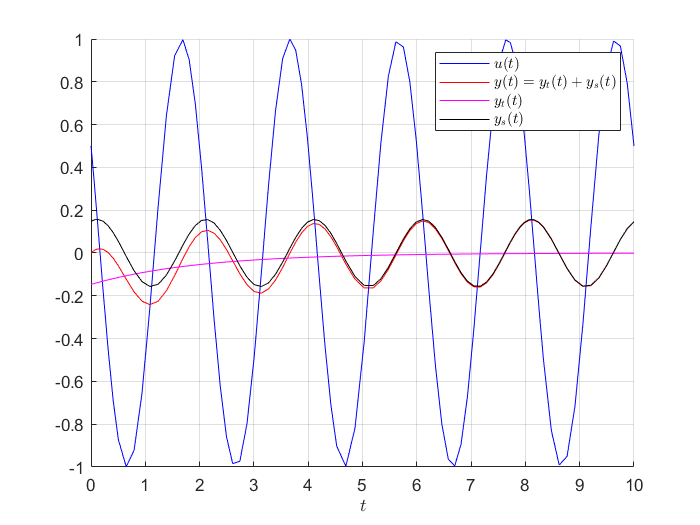

R_in = 1;
f = 0.5;
w = 2*pi*f;
phi_in = pi/3;
u = @(t)R_in*cos(w*t+phi_in); %u(t)
t_max = 10;
tspan = [0 t_max];
y0 = 0;
w_c = 1/2;
[t,y] = ode45(@(t,y)[-w_c*y+w_c*u(t)],tspan,y0);
ax = axes;
hold(ax,'on')
grid(ax,'on')
plot(ax,t,u(t),'b')
plot(ax,t,y,'r')
plot(ax,t,-R_in*w_c/(w^2+w_c^2)*(w*sin(phi_in)+w_c*cos(phi_in))*exp(-w_c*t),'m')
R_out = R_in/sqrt(1+(w/w_c)^2);
phi_out = phi_in-atan(w/w_c);
plot(ax,t,R_out*cos(w*t+phi_out),'k')
xlabel('$t$','Interpreter',"latex")
legend({'$u(t)$','$y(t)=y_t(t)+y_s(t)$','$y_t(t)$','$y_s(t)$'},'Interpreter',"latex")

จากภาพ เราจะสังเกตเห็นได้ว่า ผลตอบสนองแบบคงตัว $y_s \left(t\right)$นั้นมีลักษณะเเป็นคลื่นไซน์ที่มีแอมพลิจูดและมุมเฟสที่แตกต่างกับอินพุต และผลตอบสนองแบบชั่วครู่นั่นลู่เข้าสู่ศูนย์ เราจึงวิเคราะห์ความสัมพันธ์ของความถี่กับผลตอบสนองแบบคงตัวเท่านั้น 

กำหนดให้**อัตราส่วนขนาด (magnitude ratio) **$\left|\cdot \right|$** ของฟังก์ชันถ่ายโอน **$G$** คืออัตราส่วนระหว่างแอมพลิจูดของคลื่นเอ้าท์พุตและคลื่นอินพุต** 


$$\left|G\right|=\frac{R_{\textrm{out}} }{R_{\textrm{in}} }$$


ข้อสังเกตของอัตราส่วนขนาดมีดังต่อไปนี้

- อัตราส่วนขนาดเป็นค่าบวกเสมอเนื่องจากแอมพลิจุดของสัญญาณเป็นบวกเสมอ

- หากอัตราส่วนขนาดของฟังก์ชันถ่ายโอนน้อยกว่า 1 แอมพลิจูดของเอ้าท์พุตจะถูกลดทอนให้น้อยลง (Attenuated)

- หากอัตราส่วนขนาดของฟังก์ชันถ่ายโอนมากกว่า 1 แอมพลิจูดของเอ้าท์พุตจะถูกขยายให้เพิ่มขึ้น (Amplified)

- กำลังสองของอัตราส่วนขนาดจะเท่ากับอัตราส่วนพลังของฟังก์ชันถ่ายโอน


$${\left|G\right|}^2 =\frac{R_{\textrm{out}}^2 }{R_{\textrm{in}}^2 }$$


ตามหลักของการวิเคราะห์สัญญาณและระบบ **อัตราส่วนขนาดมักจะถูกวิเคราะห์ในหน่วยเดซิเบล (decibel)** หนึ่งใน**สาเหตุหลักของการใช้เดซิเบลคือการวิเคราะห์อัตราส่วนที่มีช่วงกว้าง **


$${\left|G\right|}_{\textrm{dB}} =20\;\log_{10} \left(\left|G\right|\right)$$


ข้อสังเกตของอัตราส่วนขนาดในเดซิเบลมีดังต่อไปนี้

- อัตราส่วนขนาดในเดซิเบลเป็นได้ทั้งบวกและลบ

- หากอัตราส่วนขนาดของฟังก์ชันถ่ายโอนในเดซิเบลน้อยกว่า 0 dB แอมพลิจูดของเอ้าท์พุตจะถูกลดทอนให้น้อยลง

- หากอัตราส่วนขนาดของฟังก์ชันถ่ายโอนในเดซิเบลมากกว่า 0 dB แอมพลิจูดของเอ้าท์พุตจะถูกขยายให้เพิ่มขึ้น 

นอกจากนี้ เรายังสามารถวิเคราะห์ เฟสการเลื่อน (phase shift)


$$\angle \left(G\right)=\phi_{\textrm{out}} -\phi_{\textrm{in}}$$


ข้อสังเกตของเฟสการเลื่อนมีดังต่อไปนี้

- เฟสการเลื่อนมีค่าอยู่ในช่วง $\left\lbrack -\pi ,\pi \right\rbrack \;\left\lbrack \textrm{rad}\right\rbrack$

- หากเฟสการเลื่อนมีค่าเป็นบวก สัญญาณเอ้าท์พุตจะถูกทำให้ล้าหลัง (Lagging)

- หากเฟสการเลื่อนมีค่าเป็นลบ สัญญาณเอ้าท์พุตจะถูกทำให้นำหน้า (Leading)